# trav techo controller design



options = bodeoptions;
options.FreqUnits = 'Hz';

load("LAG_notch_trav_thaco.mat")
figure;
gain = 0.1;
trav_techo_plent_gain=gain;
elev_theco_gain = gain;
bode(gain*simulation_trav_techo_plant,options)
title('Gain added Bode')
hold on
bode(gain*sys_mes_trav_tacho,options)
grid on

## PRINT

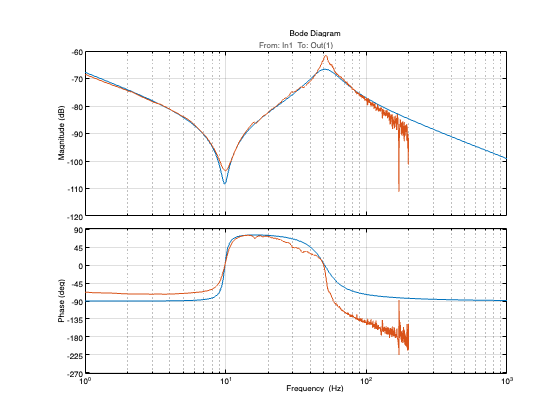

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/trav_theco_plant_sim_mes.png')

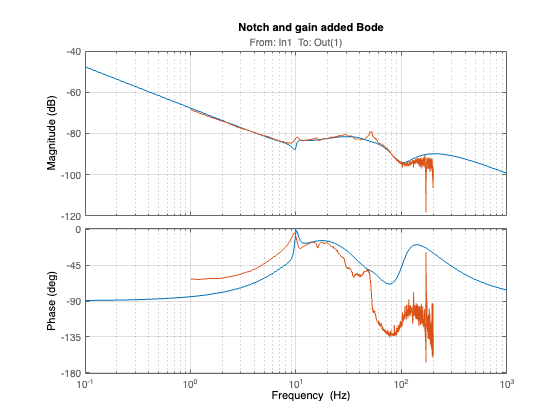

load('new_notch_10hz_elev_techo.mat')
load('new_notch_50hz_trav_tacho.mat')
load('new_notch_trav_techo_100hz.mat')
load('LAG_trav_thaco.mat')

notch_trav_techo =new_notch_10hz_elev_techo*new_notch_50hz_trav_tacho*new_notch_trav_techo_100hz;


figure;

bode(gain*notch_trav_techo*simulation_trav_techo_plant)
hold on
bode(gain*notch_trav_techo*sys_mes_trav_tacho)

title('Notch and gain added Bode')
hold off
grid on

sys_trav_theco =gain*notch_trav_techo*simulation_trav_techo_plant;
opts = pidtuneOptions('PhaseMargin',90);
[C_pi_trav_techo,info] = pidtune(sys_trav_theco,'PI',360,opts)

C_pi_trav_techo =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.43e+04, Ki = 3.37e+06
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 360
           PhaseMargin: 90.0000


Kp_trav_techo = C_pi_trav_techo.Kp;
Ki_trav_techo = C_pi_trav_techo.Ki/20;

PI_trav_techo = tf(1/s*Ki_trav_techo+Kp_trav_techo );

sys_control = PI_trav_techo*sys_trav_theco;
% bode(sys_control) 

figure;
margin(sys_control*LAG_notch_trav_thaco)
%sisotool(sys_control)
grid on
xlim([1,200])

## PRINT

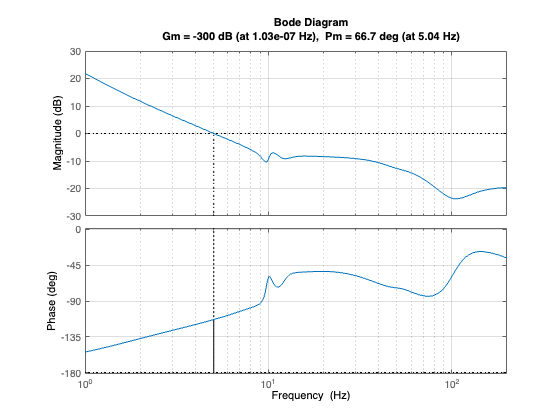

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/trav_theco_sim_controlled.png')


allmargin(sys_control)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: [112.7325 158.3349 154.6981 158.5457 129.2335]
    PMFrequency: [41.7350 67.6112 70.4821 98.2103 288.3441]
    DelayMargin: [0.0471 0.0409 0.0383 0.0282 0.0078]
    DMFrequency: [41.7350 67.6112 70.4821 98.2103 288.3441]
         Stable: 1


figure;
margin(gain*notch_trav_techo*sys_mes_trav_tacho*PI_trav_techo*LAG_notch_trav_thaco)
%sisotool(gain*notch_trav_techo*sys_mes_trav_tacho*PI_trav_techo)
grid on
xlim([1,200])

## PRINT

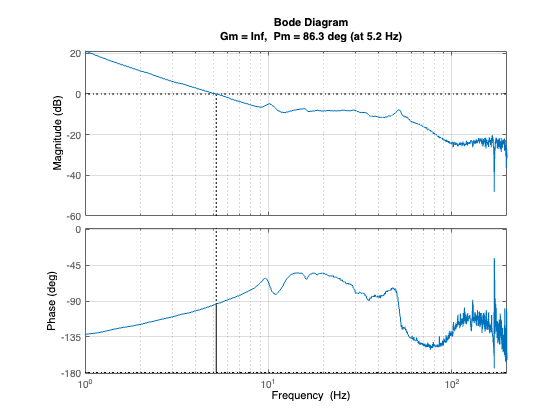

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/trav_theco_mes_controlled.png')

trav_tacho_notch =tf(notch_trav_techo*LAG_notch_trav_thaco);